% FIX EDGE CASE FOR GOING OVER PLANNED PATHS

ans = "left side too close"

ans = "right diag too close"

ans = "left diag too close"

ans = "left diag too close"

ans = "left diag too close"

ans = "left diag too close"

ans = "left diag too close"

ans = "left diag too close"

ans = "left diag too close"

ans = "left diag too close"

ans = "right diag too close"

ans = "right diag too close"

ans = "left diag too close"

ans = "left diag too close"

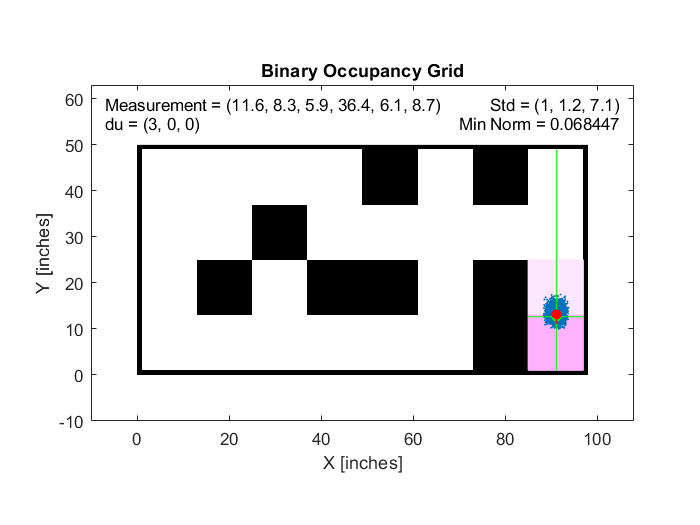

clear all;
clc;

global X Y;
X = 98;
Y = 50;

global mode TESTING SIM BLUETOOTH;
TESTING = 1;
SIM = 2;
BLUETOOTH = 3;

global phase LOCALIZING PICKUP GRIPPER DROPOFF ;
LOCALIZING = 1;
PICKUP = 2;
GRIPPER = 3;
DROPOFF = 4;

global true_pose;           % Specific to testing mode
global s_cmd s_rply;        % Specific to sim mode
global s_bt odomModel;      % specific to bluetooth mode

addpath(genpath("C:\Users\Louis\OneDrive - University of Toronto\5th Year\1 - MIE444\SimMeR-master_v4\SimMeR-master"));
           

% Initialize occupancy map
[map, thiccMap] = initializeMap();

% Initialize set of particles
initialParticles = 50000;
minParticles = 3000;
particles = initializeParticles(thiccMap, initialParticles);

% Initialize communications
mode = TESTING; 

if mode == SIM
    % Initialize tcp server to read and respond to algorithm commands
    [s_cmd, s_rply] = tcp_setup();
    fopen(s_cmd);

elseif mode == BLUETOOTH
    s_bt = serialport('COM6', 9600)
    fopen(s_bt);
    pause(0.5);
end

% Initialize odometry model
odomModel = wheelEncoderOdometryDifferentialDrive;
odomModel.InitialPose = [0, 0 , 0];
odomModel.TicksPerRevolution = [400 400];
odomModel.TrackWidth = 6.8;
odomModel.WheelRadius = [1.28 1.28];

% Initialize variables
resamplingNoiseStd = [0.7, 0.7, 0.04];   % noise applied during resampling: [x, y, theta]
odomNoiseStd = [0.04, 0.04, 0.7];        % noise applied for odometry model: [rotation1, rotation2, translation]

scanAngles = [0, pi/4, pi/2, pi, -pi/2, -pi/4];     % all ultrasonic readings
scanAngles_pf = [0, pi/2, pi, -pi/2];                % 4 ultrasonic readings used for localization

true_pose = [30, 7, pi/2];
du = [0, 0, 0];   % [delta_x, delta_y, delta_rotation] for each time step


% Initialize planning
phase = LOCALIZING;
pathInd = [];
planNextPath = false;
lastPlannedBlock = -1;
gripperComplete = false;

pickupLocation = -1;
dropoffLocation = 32;           % INPUT

autopilot = true;


% if mode == BLUETOOTH
%     for count=1:10000
%         fwrite(s_bt, 's');
%         readings = fscanf(s_bt);
%         while strtrim(readings) == "Done"
%             readings = fscanf(s_bt);
%         end
%         
%         readings = split(readings,",");
%         for i = 1:7
%             u(i) = str2num(char(readings(i))); 
%         end
%         ir = str2num(char(readings(8)));
% 
%         wander(u, ir);
%     end
% end


% Main loop
while 1
    % Get sensor readings from robot
    [u, u_pf, ir] = getSensorReadings(map, scanAngles);
    
    % Propagate movement in particles
    particles = moveParticles(map, odomNoiseStd, particles, du);
    
    % Assign weights to each particle.
    [weights, minNorm] = getLikelihood(map, scanAngles_pf, particles, u_pf);

    
    % Reinitialize all particles if none are close to robot position
%     if minNorm > 20
%         particles = initializeParticles(thiccMap, initialParticles);
%         [weights, minNorm] = getLikelihood(map, scanAngles, particles, measurement);
%     end

    % Localize
    predictedPose = weights * particles;
    currentBlock = xy2ind(predictedPose(1:2));

    % Change phases if possible
    particleStd = std(particles);

    if phase == LOCALIZING && particleStd(1) < 1.7 && particleStd(2) < 1.7 && inBlockCenter(predictedPose(1:2))
        if mode == BLUETOOTH
            fwrite(s_bt, '6');
        end
        
        if ~gripperComplete
            phase = PICKUP;
        else
            phase = DROPOFF;
        end
        planNextPath = true;
        
    elseif phase == PICKUP && currentBlock == pickupLocation && inBlockCenter(predictedPose(1:2)) 
        if mode == BLUETOOTH
            fwrite(s_bt, '6');
            gripper(pickupLocation);
        end
        
        gripperComplete = true;
        particles = initializeParticles(thiccMap, initialParticles);
        phase = LOCALIZING;
        continue;

    elseif phase == DROPOFF && currentBlock == dropoffLocation
        if mode == BLUETOOTH
            fwrite(s_bt, '9');
            fwrite(s_bt, '!');
        end
        
        break;
    end


    % Plan path if requested
    if lastPlannedBlock ~= currentBlock && inBlockCenter(predictedPose(1:2))...
            && (phase == PICKUP || phase == DROPOFF)
        planNextPath = true;
    end

    if planNextPath
        if phase == PICKUP
            [pathy1, pathInd1] = findPath(predictedPose, 3);
            [pathy2, pathInd2] = findPath(predictedPose, 17);

            if size(pathInd1, 1) < size(pathInd2, 1)
                pathy = pathy1;
                pathInd = pathInd1;
                pickupLocation = 3;
            else
                pathy = pathy2;
                pathInd = pathInd2;
                pickupLocation = 17;
            end
            planNextPath = false;

        elseif phase == DROPOFF
            [pathy, pathInd] = findPath(predictedPose, dropoffLocation);
            planNextPath = false;
        end
        moveIndex = 1;
        pathIndex = 1;
        lastPlannedBlock = currentBlock;
    end
    
    % Visualize
    visualize(map, particles, true_pose, predictedPose, u, u_pf, scanAngles_pf, minNorm, du, pathInd);
    
    % Resample particles
    resampleParticles = max(minParticles, round(0.75*size(particles, 1)));
    particles = resample(thiccMap, resamplingNoiseStd, particles, weights, resampleParticles);
    
    % Execute robot movement
    if autopilot
        if phase == LOCALIZING
            [du, ~] = wander(u, ir);    
        else
            if pathIndex <= size(pathy, 2)
                [du, pathIndex, moveIndex] = followPath(pathy, u, pathIndex, moveIndex, ir);
            else
                planNextPath = true;
            end
        end
        
    else
        du = manualMove();
    end
end

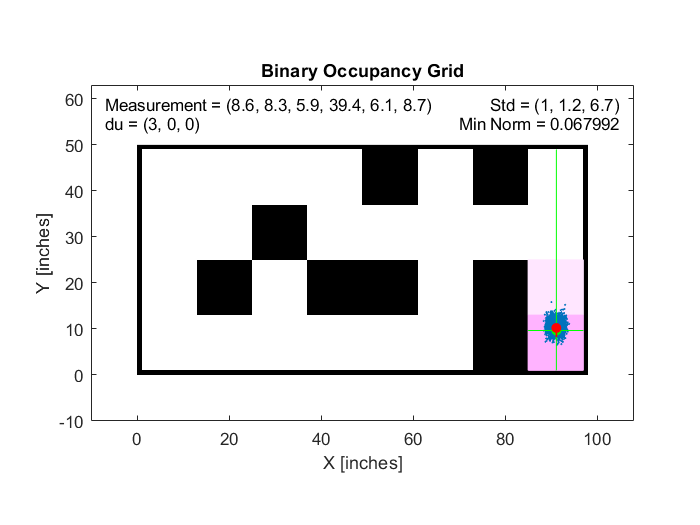


visualize(map, particles, true_pose, predictedPose, u, u_pf, scanAngles_pf, minNorm, du, pathInd);



disp("WE DONE!!");

WE DONE!!
